clear
clf
clc

%step 1
load('RandomProcessLabData.mat');

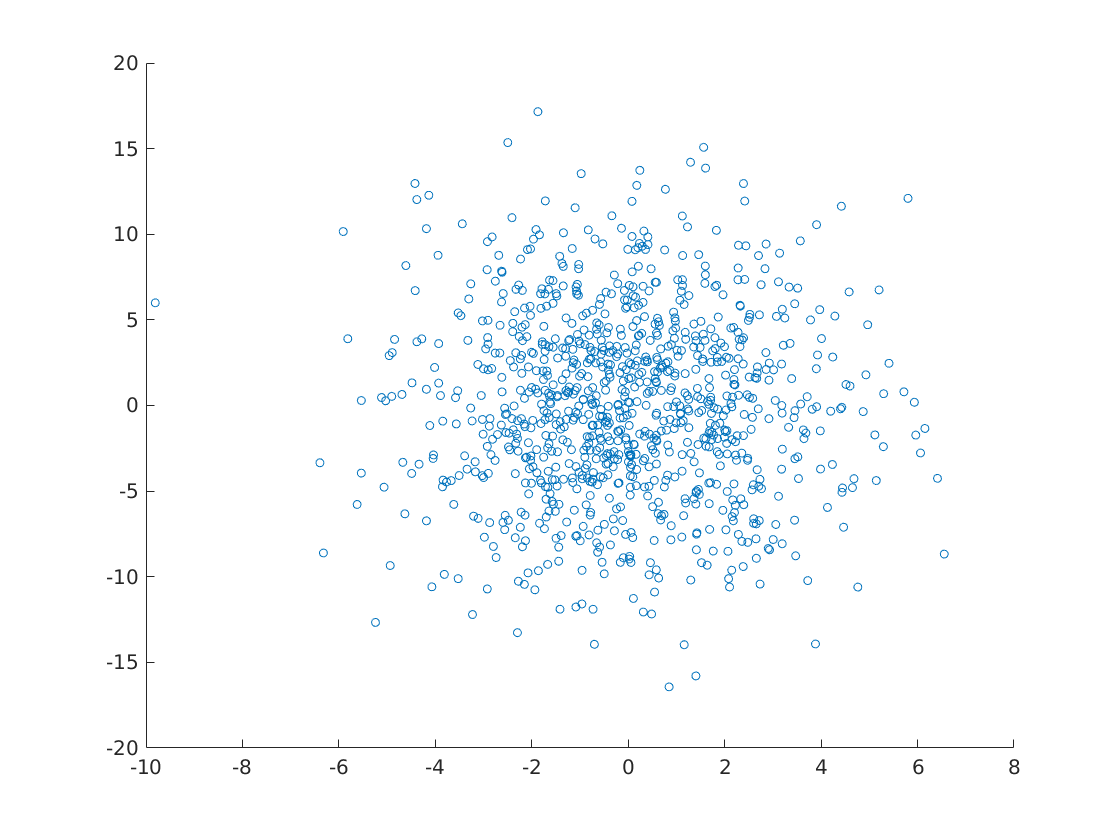

%step 2
%plot(signal(:,500))
figure();
scatter(signal(2,:),signal(100,:))

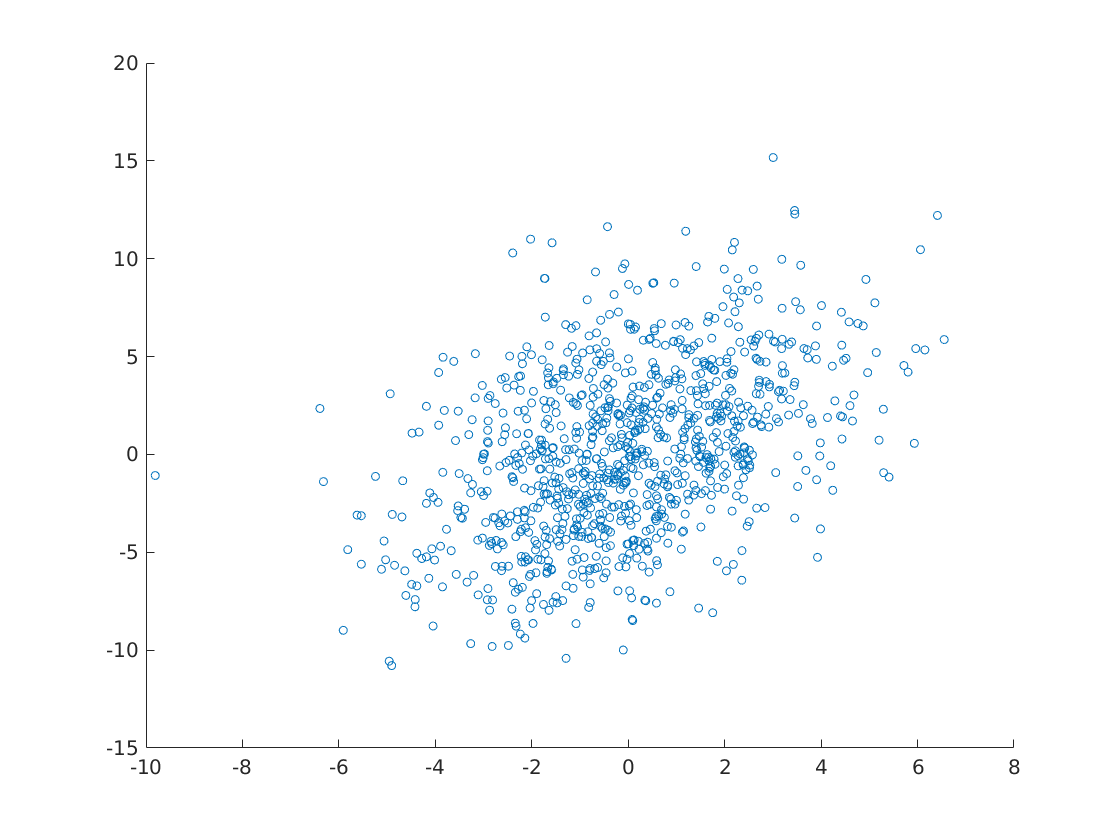

%looks uncorrellated
scatter(signal(2,:),signal(5,:))

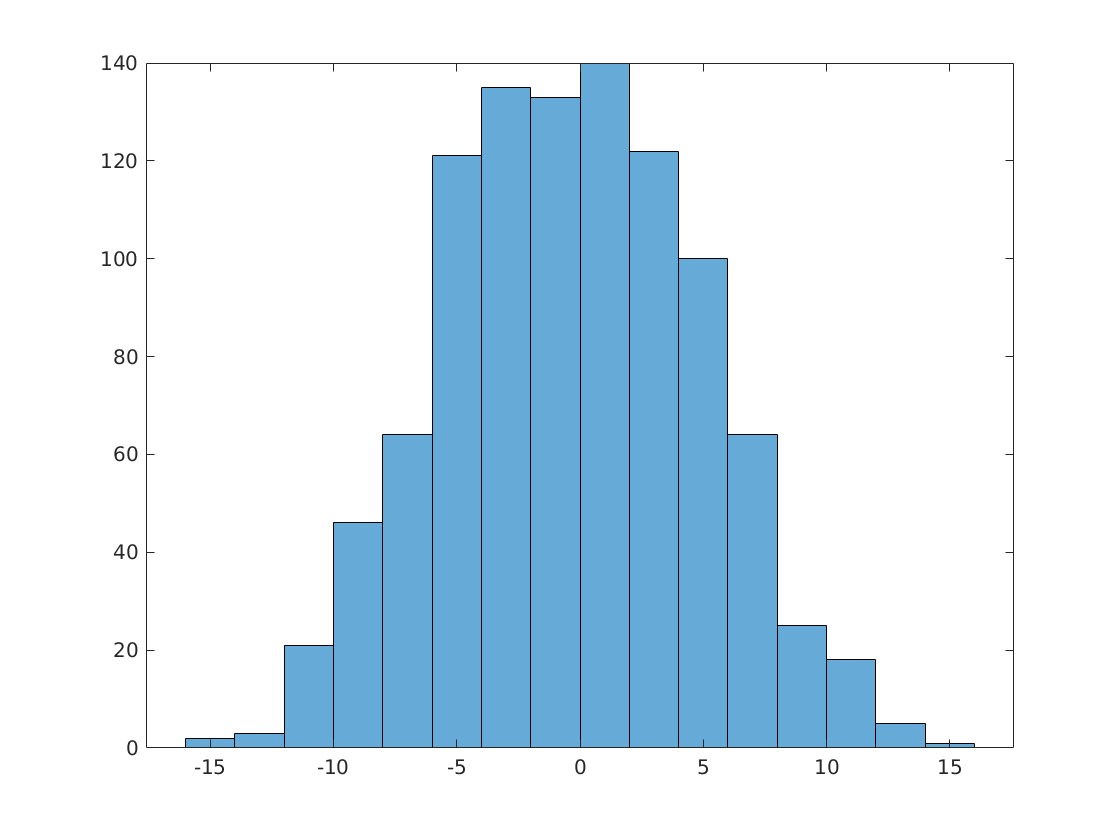

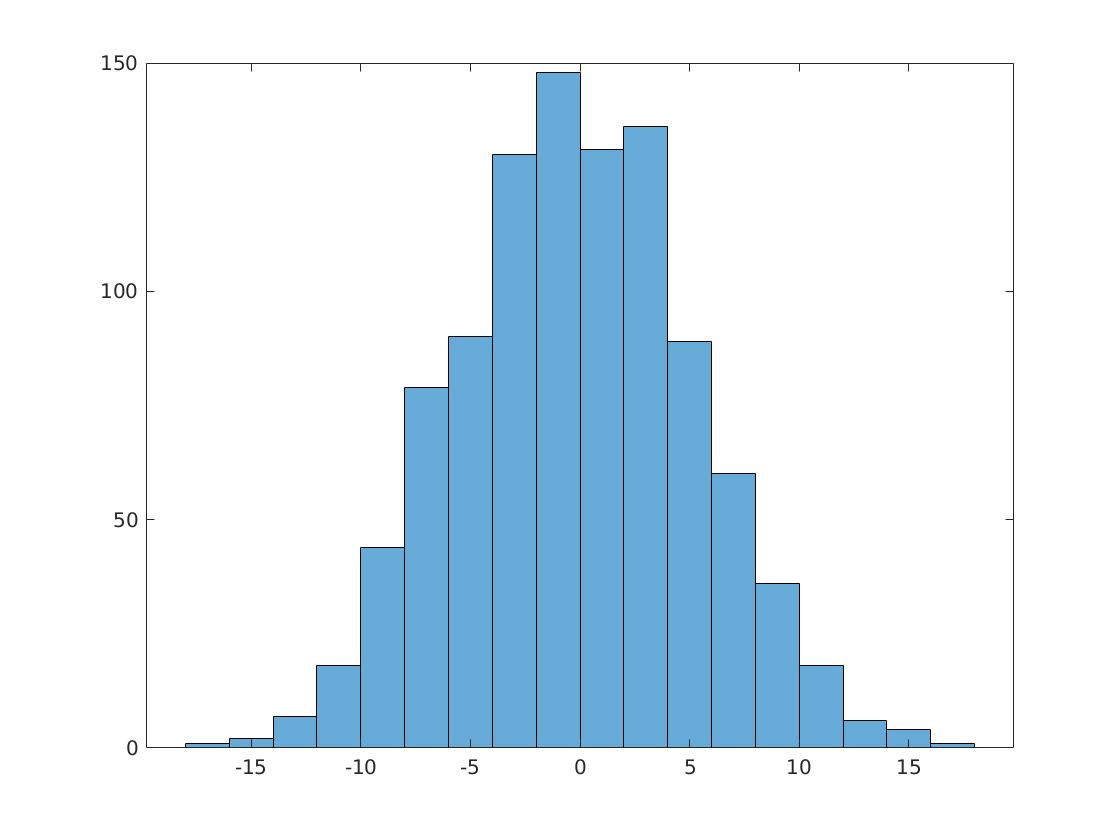

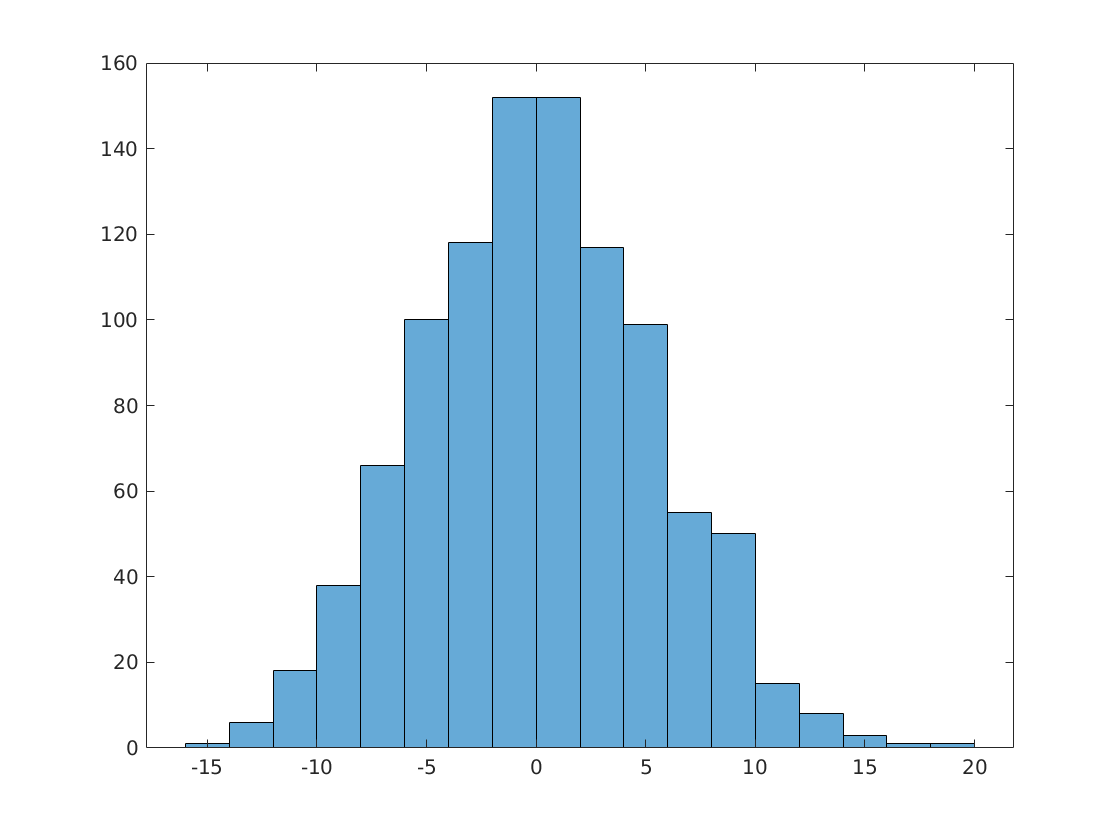

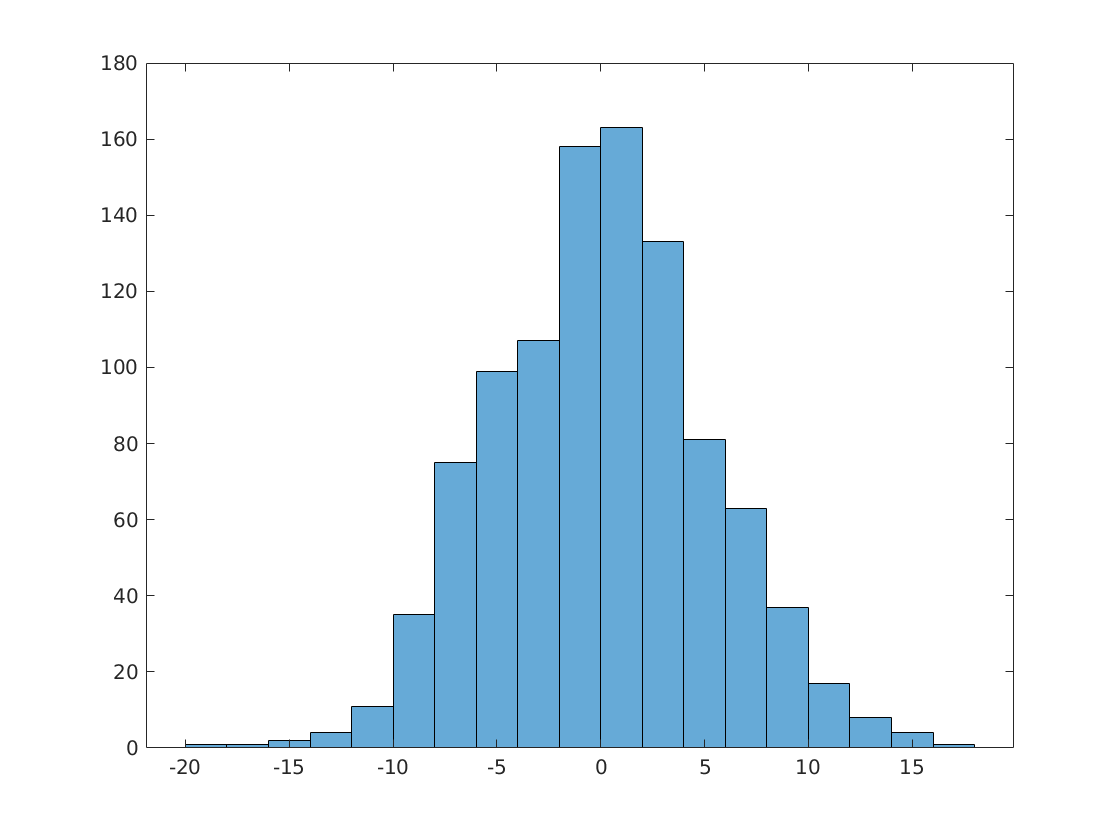

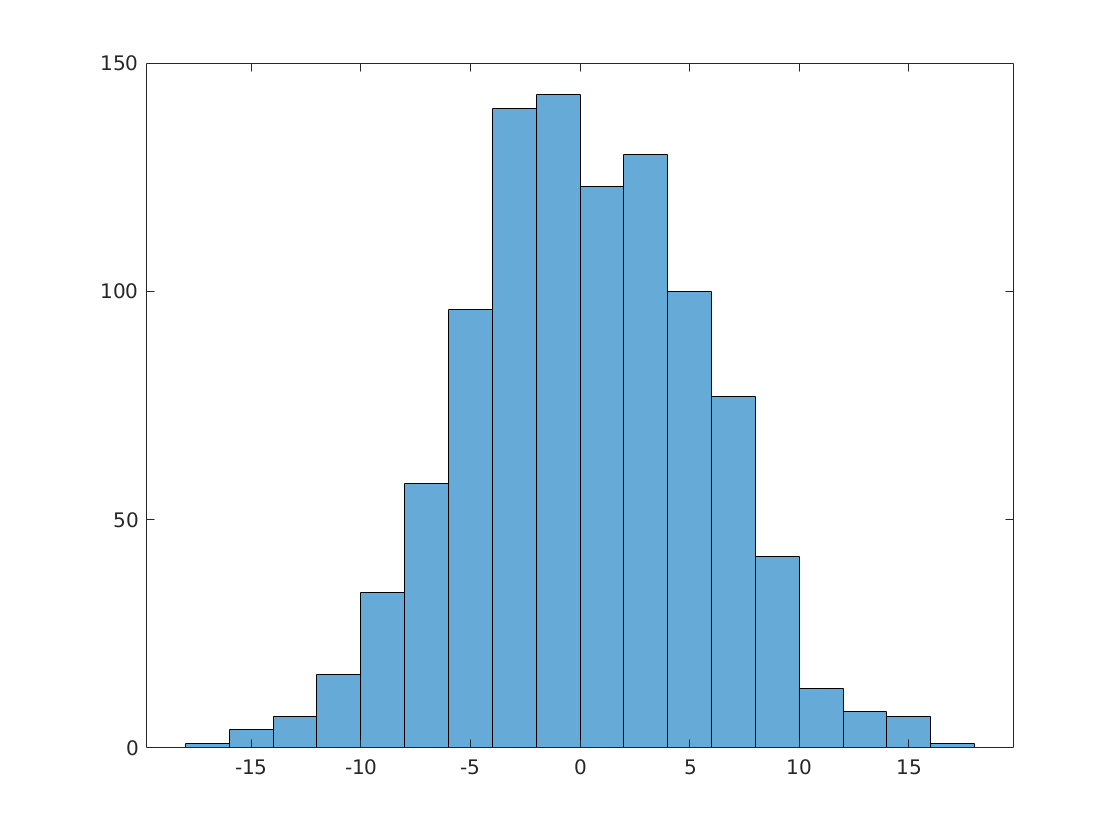

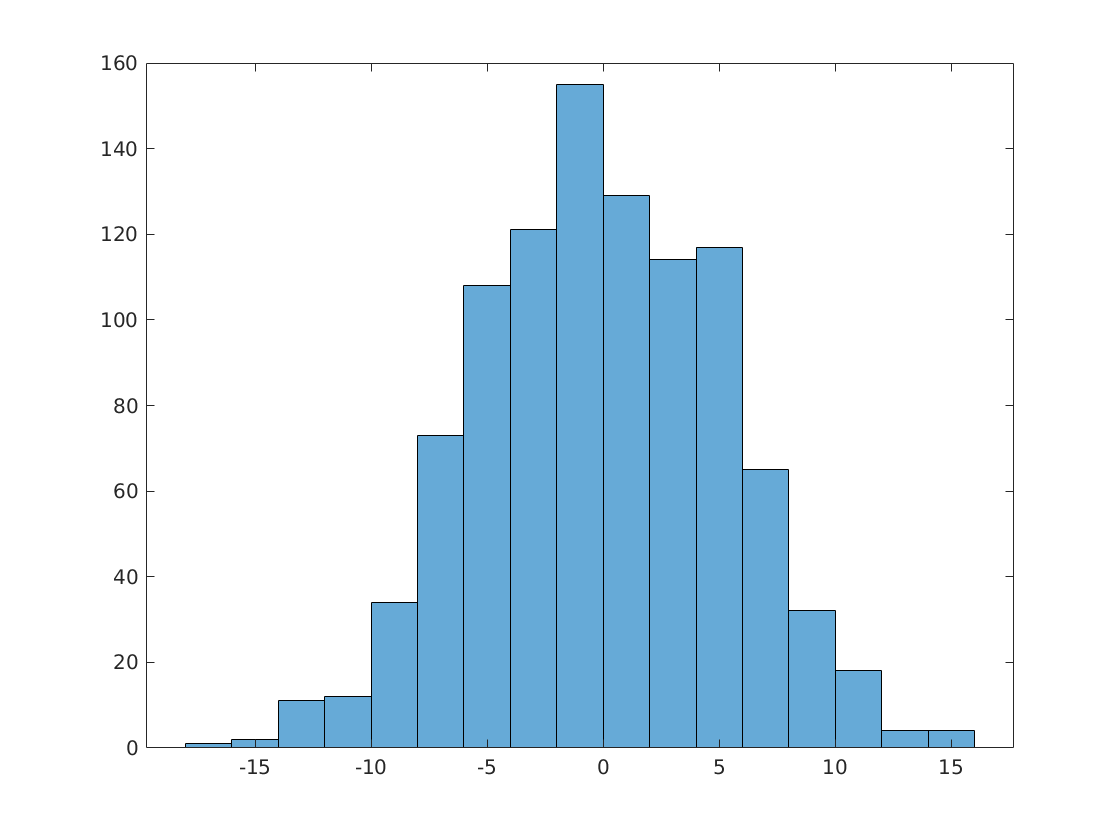

%positive correlation

for i = 25:10:75
    figure();
    histogram(signal(i,:))
end

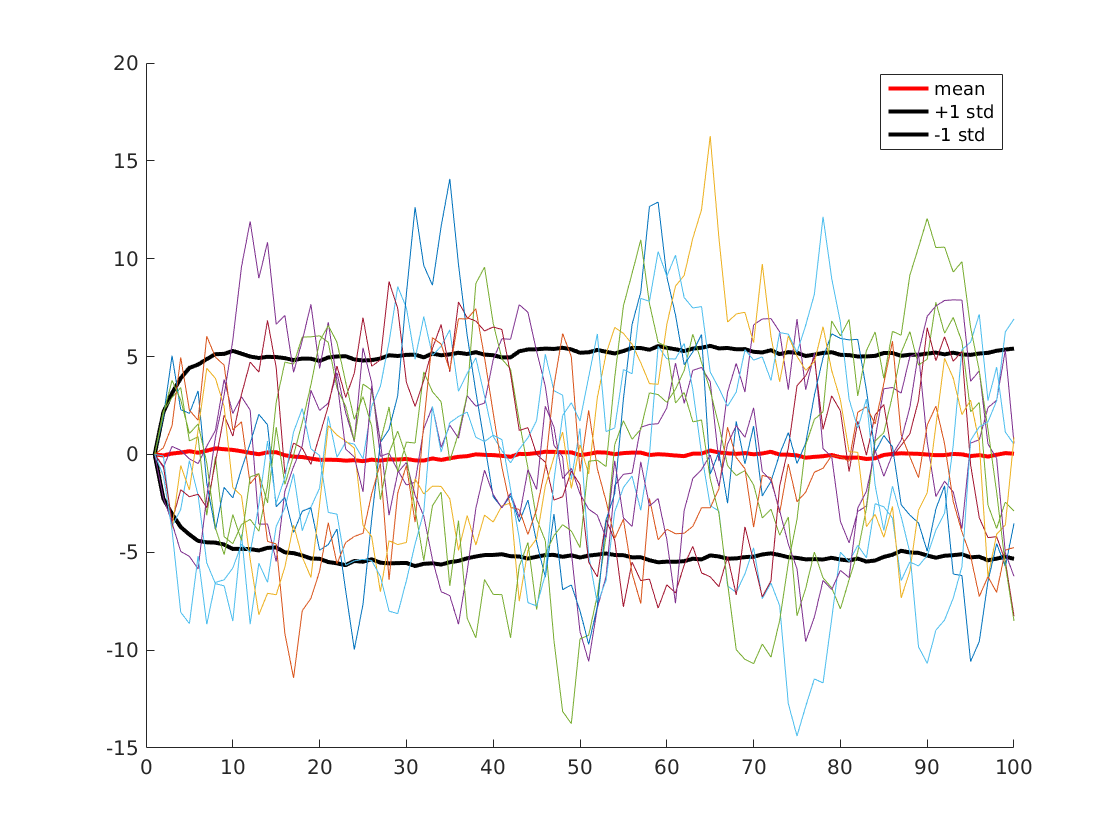

%step 3
sig_mean = zeros(100,1);
sig_std = zeros(100,1);

for i = 1:100
    sig_mean(i,1) = mean(signal(i,:));
    sig_std(i,1) = std(signal(i,:));
end

figure();
hold on
plot(sig_mean,'r','LineWidth',3)
plot(sig_mean + sig_std,'k','LineWidth',3)
plot(sig_mean - sig_std,'k','LineWidth',3)
legend('mean','+1 std','-1 std')

for i = 1:10
    plot(signal(:,i),'HandleVisibility','off')
end